clc
close all; 
clear all;

% Enter the dimensions
Nx = 101;     % Number of X-grids
Ny = 101;     % Number of Y-grids
mpx = ceil(Nx/2); % Mid-point of x
mpy = ceil(Ny/2); % Mid point of y
Ni = 500;  % Number of iterations for the Poisson solver
V = zeros(Nx,Ny);   % Potential (Voltage) matrix
T = 100;             % Top-wall potential
B = 100;             % Bottom-wall potential
L = -100;            % Left-wall potential
R = -100;            % Right-wall potential

%-------------------------------------------------------------------------%
% Initializing edges potentials
%-------------------------------------------------------------------------%
V(1,:) = L;
V(Nx,:) = R;
V(:,1) = B;
V(:,Ny) = T;

%-------------------------------------------------------------------------%
% Initializing Corner potentials
%-------------------------------------------------------------------------%
V(1,1) = 0.5*(V(1,2)+V(2,1));
V(Nx,1) = 0.5*(V(Nx-1,1)+V(Nx,2));
V(1,Ny) = 0.5*(V(1,Ny-1)+V(2,Ny));
V(Nx,Ny) = 0.5*(V(Nx,Ny-1)+V(Nx-1,Ny));

%-------------------------------------------------------------------------%
eps_0 = 8.854*(10^-12); % Absolute permittivity (of free space)
eps_r = 1;              % Relative permittivity of the medium
eps = eps_0*eps_r;
charge_order = 10^-9; % milli, micro, nano etc..
n = 4; % How many charges?
Q = [2,-2,-2,2]*charge_order; % What are the charges?
% Array of charge locations (Actual coordinates in a Cartesian Plane)
X = 0.5*[10,10,-10,-10]; % Where are the charges located?
Y = 0.5*[10,-10,10,-10];  
X = X+mpx;  % Relative coordinates for computation
Y = Y+mpy;
Rho = zeros(Nx,Ny);  % Charge distribution matrix
for k = 1:n 
        Rho(X(k),Y(k)) = Q(k)/eps;
end

%-------------------------------------------------------------------------%
%           Computing potentials in the box
%-------------------------------------------------------------------------%
for l = 1:n     % Repeat for all charges
        
    for z = 1:Ni    % Number of iterations
        
        for i=2:Nx-1
        for j=2:Ny-1
                V(i,j)=0.25*(V(i+1,j)+V(i-1,j)+V(i,j+1)+V(i,j-1)+Rho(i,j));
        end
        end
        
    end
    
end

%-------------------------------------------------------------------------%
% Take transpose for proper x-y orientation
V = V';
E = gradient(V);
E = -E;
[Ex,Ey] =gradient(V);
Ex = -Ex;
Ey = -Ey;
  
x_range = (1:Nx)-mpx;
y_range = (1:Ny)-mpy;

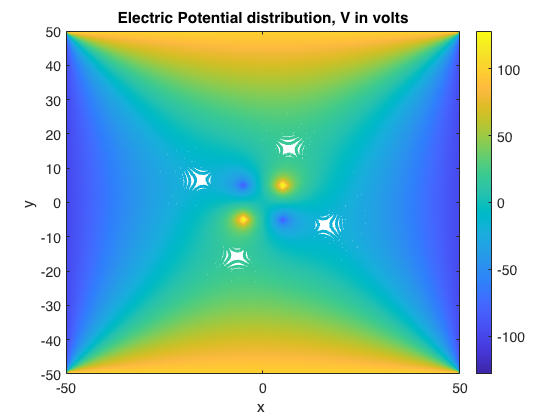

% Contour Display for electric potential
figure(1)
contour_range_V = -130:1:130;
contour(x_range,y_range,V,contour_range_V,'linewidth',3);
axis([min(x_range) max(x_range) min(y_range) max(y_range)]);
colorbar('location','eastoutside','fontsize',14);
xlabel('x ','fontsize',14);
ylabel('y ','fontsize',14);
title('Electric Potential distribution, V in volts','fontsize',14);
h1=gca;
set(h1,'fontsize',14);

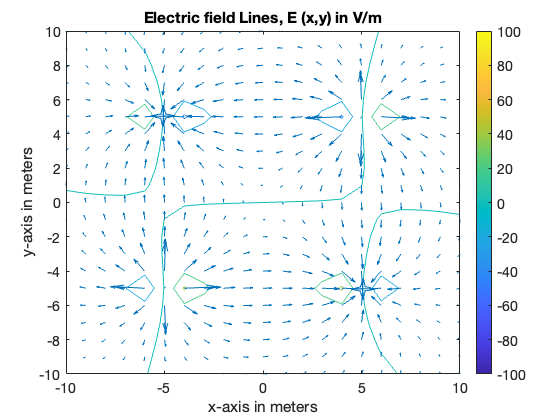

fh1 = figure(1); 
set(fh1, 'color', 'white')
% Quiver Display for electric field Lines
figure(2)
contour(x_range,y_range,E,'linewidth',0.5);
hold on;
quiver(x_range,y_range,Ex,Ey,4);
axis([-10 10 -10 10]);
title('Electric field Lines, E (x,y) in V/m','fontsize',14);
colorbar('location','eastoutside','fontsize',14);
xlabel('x-axis in meters','fontsize',14);
ylabel('y-axis in meters','fontsize',14);
h2=gca;
set(h2,'fontsize',14);

fh2 = figure(2); 
set(fh2, 'color', 'white')
